# Regolazione trascrizione genica

La trascrizione è il processo mediante il quale l'RNA messaggero (mRNA) viene generato dal segmento del DNA. La regione del promotore di un gene consente il controllo della trascrizione mediante altre proteine, che si legano alla regione del promotore e reprimono o attivano l'RNA polimerasi, l'enzima che effettua la trascrizione dell'mRNA dal DNA. L'mRNA viene quindi tradotto in una proteina secondo la sua sequenza nucleotidica.

Si consideri la regolazione di una proteina $A$ con una concentrazione data da $p_a$ e una corrispondente concentrazione di mRNA $m_a$. Sia $B$ una seconda proteina con concentrazione $p_b$ che inibisce la produzione di proteina $A$ attraverso la regolazione trascrizionale. La dinamica risultante di $p_a$ e $m_a$ può essere scritta nella forma:


$$\begin{cases}
\dot{m}_a = \frac{a_{ab}}{1+k_{ab}p_b^{n_{ab}}}+a_{a0} - \gamma_am_a\\
\dot{p}_a = \beta_am_a-\delta_ap_a\\
y = p_a
\end{cases}$$


clear all, close all, clc;
warning('off','all');

n_ab = 3

n_ab = 3

a_ab = 0.5

a_ab = 0.5000

k_ab = 6.25*10^(-4)

k_ab = 6.2500e-04

a_a0 = 5*10^(-4)

a_a0 = 5.0000e-04

gamma = 5.8*10^(-3)

gamma = 0.0058

beta = 0.12

beta = 0.1200

delta = 1.2*10^(-3)

delta = 0.0012

I precedenti parametri sono stati presi dal libro *Feedback Systems* di *Astrom and Murray*.

## Linearizzazione globale

Se si sceglie l'ingresso di controllo $p_b$ nella forma:


$$p_b = \sqrt[n_{ab}]{\frac{1}{k_{ab}}\left(\frac{a_{ab}}{v}-1\right)}$$


si ottiene una linearizzazione globale del sistema. Il nuovo sistema lineare sarà:


$$\begin{cases}
\dot{m}_a =  - \gamma_am_a+ v + a_{a_0}\\
\dot{p}_a = \beta_am_a-\delta_ap_a\\
y = p_a
\end{cases}$$


che espresso in forma matriciale sarà:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{m_a } \\
\dot{p_a } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\gamma \; & 0\\
\beta  & -\delta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_a \\
p_a 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack v+\left\lbrack \begin{array}{c}
a_{a_0 } \\
0
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_a \\
p_a 
\end{array}\right\rbrack 
\end{array}$$


As = [-gamma 0; beta -delta]

As =    -0.0058         0
    0.1200   -0.0012


Bs = [1; 0]

Bs =      1
     0


Cs = [0 1]

Cs =      0     1


Ds = 0

Ds = 0

## Raggiungibilità

Si verifica la raggiungibilità verificando che la matrice di raggiungibilità $W_r$ abbia determinante diverso da $0$ o in maniera equivalente rango pieno. In questo caso il rango deve essere $2$.

Wr = [Bs As*Bs As^2*Bs]

Wr =     1.0000   -0.0058    0.0000
         0    0.1200   -0.0008


rango = rank(Wr)

rango = 2

## Regolatore lineare quadratico (LQR)

La prima strategia di controllo applicata è LQR.

### Azione integrale

La presenza di un disturbo $a_{a0}$ impone l'utilizzo di un'azione integrale per la sua reiezione. L'azione integrale viene introdotta aumentando la descrizione del sistema con un nuovo stato:


$$\dot{z} =y-r=C\;x-r$$


Così da ottenere:


$$\begin{cases}
\dot{m}_a =  - \gamma_am_a+ v + a_{a_0}\\
\dot{p}_a = \beta_am_a-\delta_ap_a\\
\dot{z} = p_a - r
\end{cases}$$


o in maniera equivalente:


$$\begin{array}{l}
\dot{\tilde{x} } =\left\lbrack \begin{array}{c}
\dot{m_a } \\
\dot{p_a } \\
\dot{z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\gamma  & 0 & 0\\
\beta  & -\delta  & 0\\
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_a \\
p_a \\
z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack v+\left\lbrack \begin{array}{c}
a_{a_0 } \\
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
r
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{ccc}
0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_a \\
p_a \\
z
\end{array}\right\rbrack 
\end{array}$$


A = [-gamma 0 0; beta -delta 0; 0 1 0]

A =    -0.0058         0         0
    0.1200   -0.0012         0
         0    1.0000         0


B = [1; 0; 0]

B =      1
     0
     0


C = [0 1 0]

C =      0     1     0


D = 0

D = 0

### Applicazione LQR

Si definiscono le funzioni di costo $Q_z$ e $Q_u$:

w1 = 1;
w2 = 1;
w3 = 300;

Qz = [w1 0 0; 0 w2 0; 0 0 w3];
Qu = 0.01;

Il controllore che si deve realizzare avrà forma:

$v=-\textrm{Kx}-k_i z+k_r r$.

Il guadagno ottimale $K$ si ottiene utilizzando il comando "lqr":

[K,S,P] = lqr(A,B,Qz,Qu)

K =    12.0261  186.5251  173.2051


S =     0.1203    1.8653    1.7321
    1.8653  172.6055  173.6652
    1.7321  173.6652  323.2793


P =   -1.0158 + 1.0229i
  -1.0158 - 1.0229i
 -10.0014 + 0.0000i


dove il $3°$ elemento è il guadagno $k_i$.

ki = K(3)

ki = 173.2051

Kp = K(1:2)

Kp =    12.0261  186.5251


La matrice $k_r$ si ottiene come:


$$k_r =-\frac{1}{{C\left(A-\textrm{BK}\right)}^{-1} B}$$


kr = -1/(C*inv(A-B*K)*B)

kr = -Inf

## Pole placement

Poiché il disturbo $a_{a_0 }$ è molto piccolo, nell'applicazione del pole placement verrà semplicemente trascurato e si prenderà come riferimento il sistema ottenuto mediante la linearizzazione globale, senza l'introduzione di un'azione integrale.

### Applicazione pole placement

Per avere a ciclo chiuso un comportamento privo di sovraelongazione e un tempo di salita pari a $T_r =1s$, si impongono i seguenti valori:


$$\begin{array}{l}
\zeta =0\ldotp 9\\
T_r =\frac{2\ldotp 7}{\omega_0 }\leftrightarrow \omega_0 =\frac{2\ldotp 7}{T_r }=2\ldotp 7
\end{array}$$


Il polinomio caratteristico desiderato sarà quindi nella forma:


$$p\left(s\right)=s^2 +2\zeta \omega_0 s+\omega_0^2 =s^2 +4\ldotp 86s+7\ldotp 29$$


I poli desiderati, ottenuti come radici del polinomio, devono quindi essere collocati in:

p = [-2.34-1.17i, -2.34+1.17i]

p =   -2.3400 - 1.1700i  -2.3400 + 1.1700i


Il controllore che si deve realizzare avrà forma:

$v=-\textrm{Kx}+k_r r$.

Il collocamento dei poli si effettua con il comando "place" che restituisce la matrice di guadagno $K$.

K_pp = place(As, Bs, p)

K_pp =     4.6730   56.9907


La matrice $k_r$ si ottiene come


$$k_r =-\frac{1}{{C\left(A-\textrm{BK}\right)}^{-1} B}$$


kr_pp = -1/(Cs*inv(As-Bs*K_pp)*Bs)

kr_pp = 57.0375

## Osservatore

In questa sezione si vuole progettare un osservatore, tenendo in considerazione il sistema linearizzato senza l'introduzione dell'azione integrale.

### Verifica osservabilità

Si verifica l'osservabilità verificando che la matrice di osservabilità $W_o$ abbia determinante diverso da $0$ o in maniera equivalente rango pieno. In questo caso il rango deve essere $2$.

Wo = [Cs; Cs*As; Cs*As^2]

Wo =          0    1.0000
    0.1200   -0.0012
   -0.0008    0.0000


rango = rank(Wo)

rango = 2

### Progettazione osservatore

L'osservatore avrà forma:


$$\dot{\hat{x} } =A\hat{x} +\textrm{Bu}+L\left(y-C\hat{x} \right)$$


e viene progettato utilizzando la tecnica dell'LQR. Utilizzando la dualità tra pole placement e la progettazione di un osservatore:


$$A\leftrightarrow A^T ,B\leftrightarrow C^T ,K\leftrightarrow L^T$$


si ottiene la matrice $L$ come

w1 = 1;
w2 = 100;

Qx = [w1 0; 0 w2];
Qu = 1;

[L,S,P] = lqr(As.',Cs.', Qx , Qu);
L = L.'

L =     0.6270
   10.0063


## Filtro di Kalman

Nell'ipotesi di misurazioni rumorose, in questa sezione si vuole progettare un filtro di Kalman, tenendo in considerazione il sistema linearizzato senza l'introduzione dell'azione integrale.

Il filtro di Kalman ha forma di un osservatore lineare:


$$\dot{\hat{x} } =A\hat{x} +\textrm{Bu}+L\left(y-C\hat{x} \right)$$


e si ottiene mediante il comando $\textrm{lqe}$:

G = [1 0; 0 1]

G =      1     0
     0     1


Q = [0 0; 0 0.1];
R = 100;

[L_k,P,E] = lqe(As, G, Cs, Q, R)

L_k =          0
    0.0304


P =          0         0
         0    3.0446


E =    -0.0058
   -0.0316


## Analisi del sistema a ciclo chiuso

In questa sezione viene effetuata un'analisi del sistema a ciclo chiuso considerando il sistema senza azione integrale, con il controllore ottenuto mediante pole placement.

### Punti di equilibrio

Per il calcolo dei punti di quilibrio si considerano le equazioni di stato del sistema a ciclo chiuso:


$$\begin{cases}
\frac{a_{ab}}{1+k_{ab}\left(p_b(t) = \sqrt[n_{ab}]{\frac{1}{k_{ab}}\left(\frac{a_{ab}}{-Kx+k_rr}-1\right)}\right)^{n_{ab}}}+a_{a0} - \gamma_am_a = 0\\
\beta_am_a-\delta_ap_a=0
\end{cases}$$


syms m_a p_a 

dp_a = beta*m_a - delta*p_a;
dm_a = a_ab/(1 + k_ab*(nthroot((1/k_ab)*(a_ab/(-4.6730*m_a - 56.9907*p_a + 57.0375*(25+sin(2*pi*0.01)))-1), 3))^3) +a_a0 - gamma*m_a;

sol = solve([dm_a==0, dp_a==0], [m_a, p_a]);

### Jacobiano, autovalori e autovettori

Si calcola lo Jacobiano differenziando le equazioni di stato rispetto a ciascuno stato e si valuta nei punti di equilibrio, ottenendo la matrice dinamica del sistema a ciclo chiuso.

J = jacobian([dm_a, dp_a],[m_a p_a])

$$J = \begin{array}{l} \left(\begin{array}{cc} \frac{4673\,\sigma_{1}}{4000\,\left(\frac{800}{\sigma_{2}}+1600\right)\,{\left(\frac{\sigma_{1}}{1600}+1\right)}^{2}\,{\sigma_{2}}^{2}}-\frac{29}{5000} & \frac{8020727977611991\,\sigma_{1}}{562949953421312\,\left(\frac{800}{\sigma_{2}}+1600\right)\,{\left(\frac{\sigma_{1}}{1600}+1\right)}^{2}\,{\sigma_{2}}^{2}}\\ \frac{3}{25} & -\frac{3}{2500} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sqrt[{3}]{-\frac{800}{\sigma_{2}}-1600}}^{3}\\ \sigma_{2}=\frac{4673\,m_{a}}{1000}+\frac{8020727977611991\,p_{a}}{140737488355328}-\frac{3143545336704025}{2199023255552} \end{array}$$


m_a = double(sol.m_a)

m_a = 0.2506

p_a = double(sol.p_a)

p_a = 25.0628


Md = eval(J)

Md =    -4.6788  -56.9907
    0.1200   -0.0012


Gli autovalori della matrice dinamica saranno:

[V,D] = eig(Md);
li = diag(D)

li =   -2.3400 + 1.1700i
  -2.3400 - 1.1700i


Gli autovettori invece:

v1 = V(:, 1)

v1 =    0.9989 + 0.0000i
  -0.0410 - 0.0205i


v2 = V(:, 2)

v2 =    0.9989 + 0.0000i
  -0.0410 + 0.0205i


## Simulink

open_system('transcriptional_regulation.slx')
open_system('transcriptional_regulation_observer.slx')
open_system('transcriptional_regulation_kalman_filter.slx')

## Plotting results

Plot della risposta del sistema applicando LQR.

close all;
figure(1);
clf reset
plotbrowser('on');
title('Transcriptional regulation response', 'FontSize',18)
subplot(2, 1, 1);

control = 1;
out = sim('transcriptional_regulation.slx');

pl = plot(out.t, out.p_a);
set(pl,'linewidth',2, 'Color', 'b');
leg = legend('LQR', 'Interpreter','Latex');
set(leg,'fontsize',16)
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

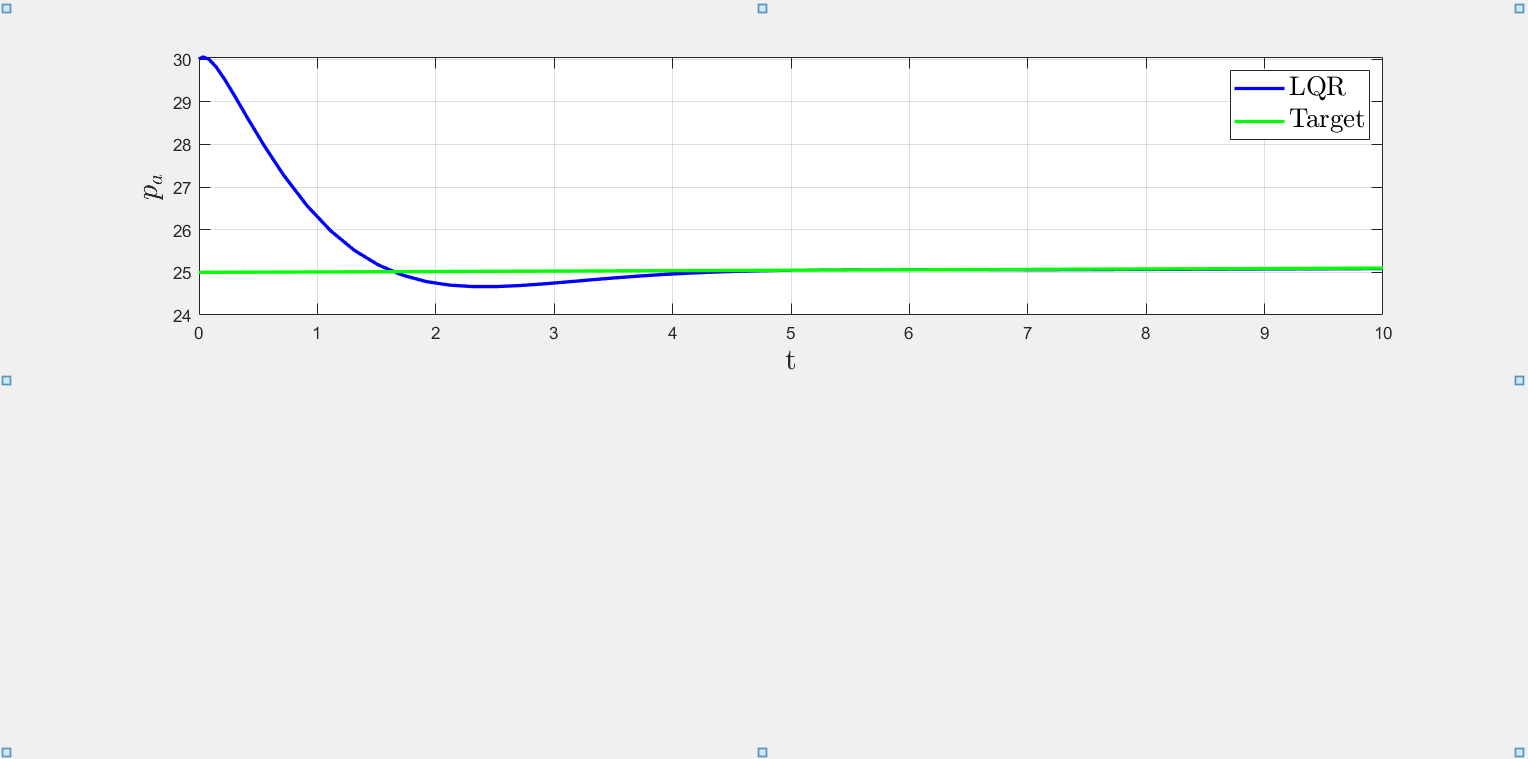

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off

Plot della risposta del sistema applicando PP.

subplot(2, 1, 2);

control = 0;
out = sim('transcriptional_regulation.slx');

pl = plot(out.t, out.p_a, 'Color', 'b');
set(pl,'linewidth',2);
leg = legend('PP', 'Interpreter','Latex');
set(leg,'fontsize',16)
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

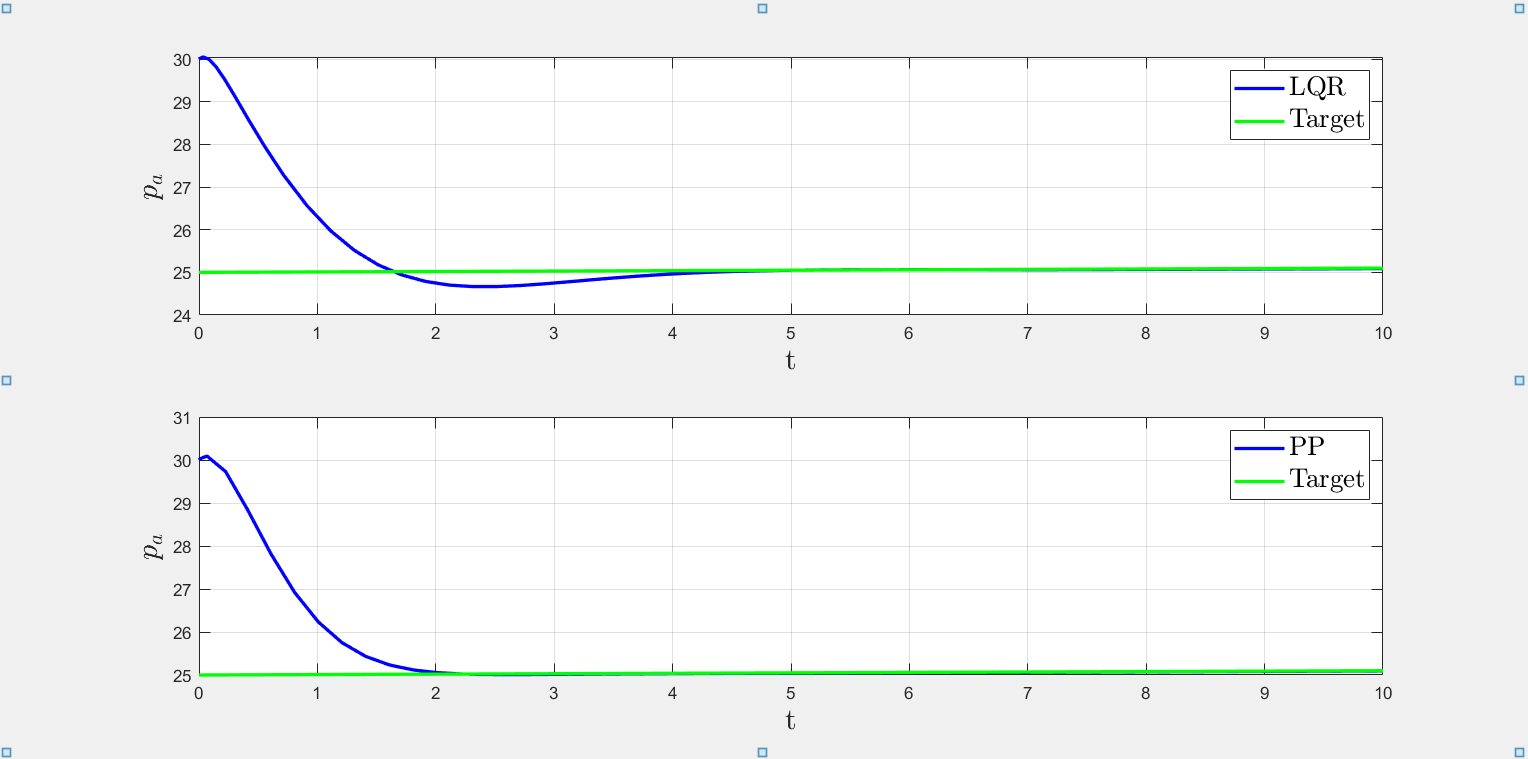

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off

Plot della risposta del sistema applicando LQR con Observer.

figure(2);
clf reset
plotbrowser('on');
title('Transcriptional regulation response Observer', 'FontSize',18)
subplot(2, 1, 1);

control = 1;
out = sim('transcriptional_regulation_observer.slx');

pl = plot(out.t, out.p_a, 'Color', 'b');
set(pl,'linewidth',2);
leg = legend('LQR Observer', 'Interpreter','Latex');
set(leg,'fontsize',16)
hold on
pl = plot(out.t, out.p_a_noobserver, 'Color', 'r', 'DisplayName','LQR No Observer');
set(pl,'linewidth',2);
hold off
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

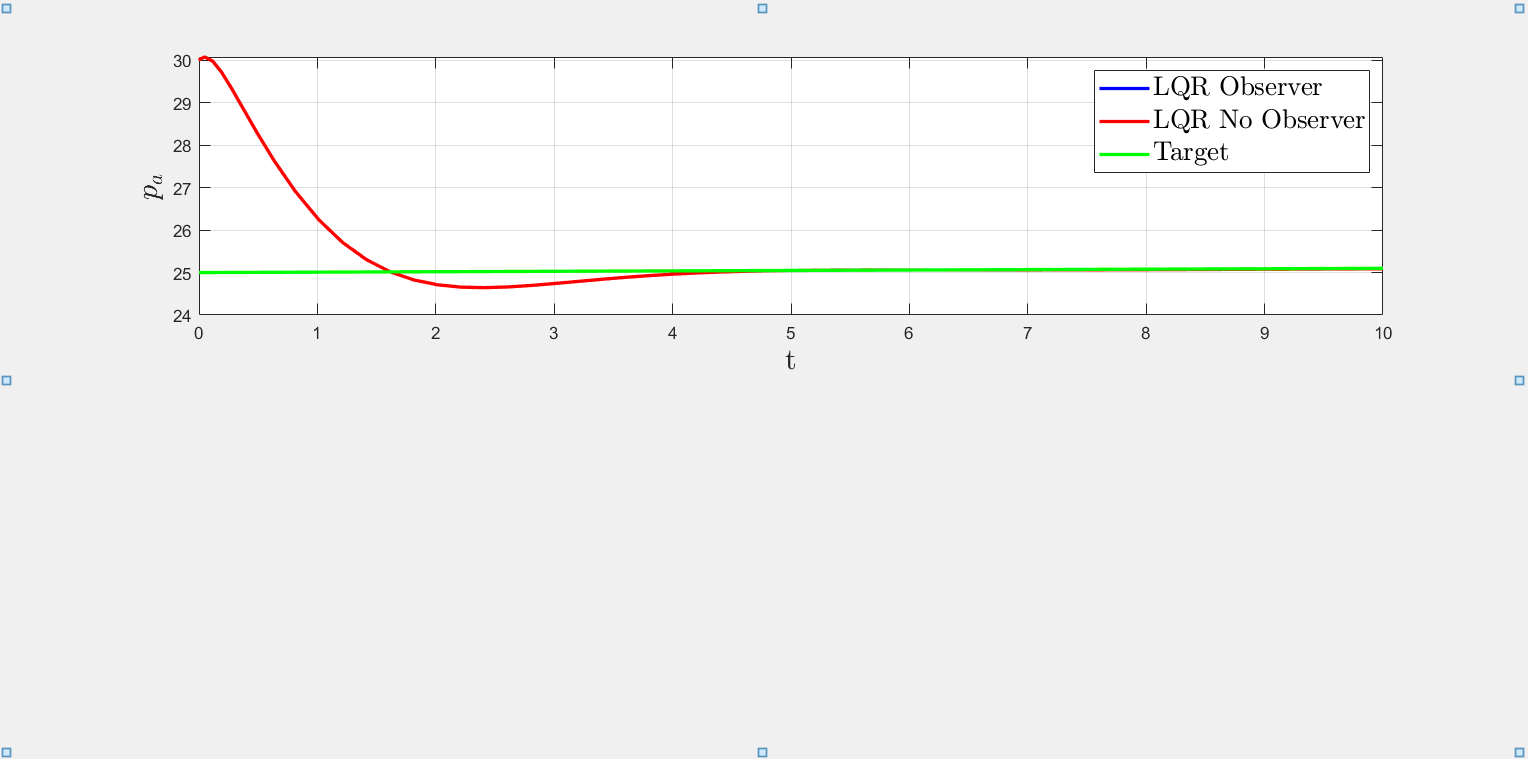

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off

Plot della risposta del sistema applicando PP con Observer.

subplot(2, 1, 2);

control = 0;
out = sim('transcriptional_regulation_observer.slx');

pl = plot(out.t, out.p_a, 'Color', 'b');
set(pl,'linewidth',2);
leg = legend('PP Observer', 'Interpreter','Latex');
set(leg,'fontsize',16)
hold on
pl = plot(out.t, out.p_a_noobserver, 'Color', 'r', 'DisplayName','PP No Observer');
set(pl,'linewidth',2);
hold off
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

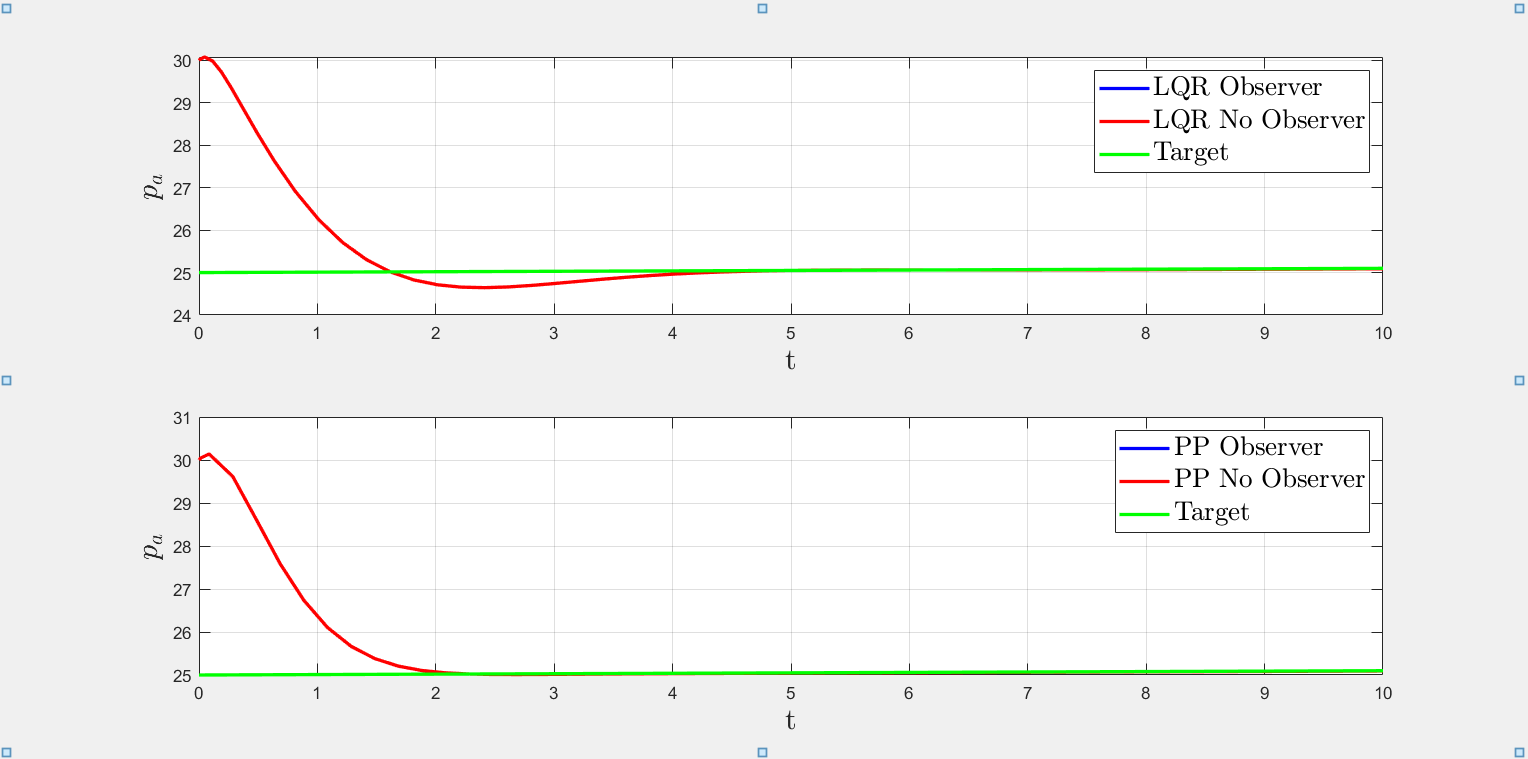

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off

Plot della risposta del sistema applicando LQR con filtro di Kalman.

figure(3);
clf reset
plotbrowser('on');
title('Transcriptional regulation response Kalman filter', 'FontSize',18)
subplot(2, 1, 1);

control = 1;
out = sim('transcriptional_regulation_kalman_filter.slx');

pl = plot(out.t, out.p_a, 'Color', 'b');
set(pl,'linewidth',2);
leg = legend('LQR Kalman Filter', 'Interpreter','Latex');
set(leg,'fontsize',16)
hold on
pl = plot(out.t, out.p_a_nofilter, 'Color', 'r', 'DisplayName','LQR No Filter');
set(pl,'linewidth',2);
hold off
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

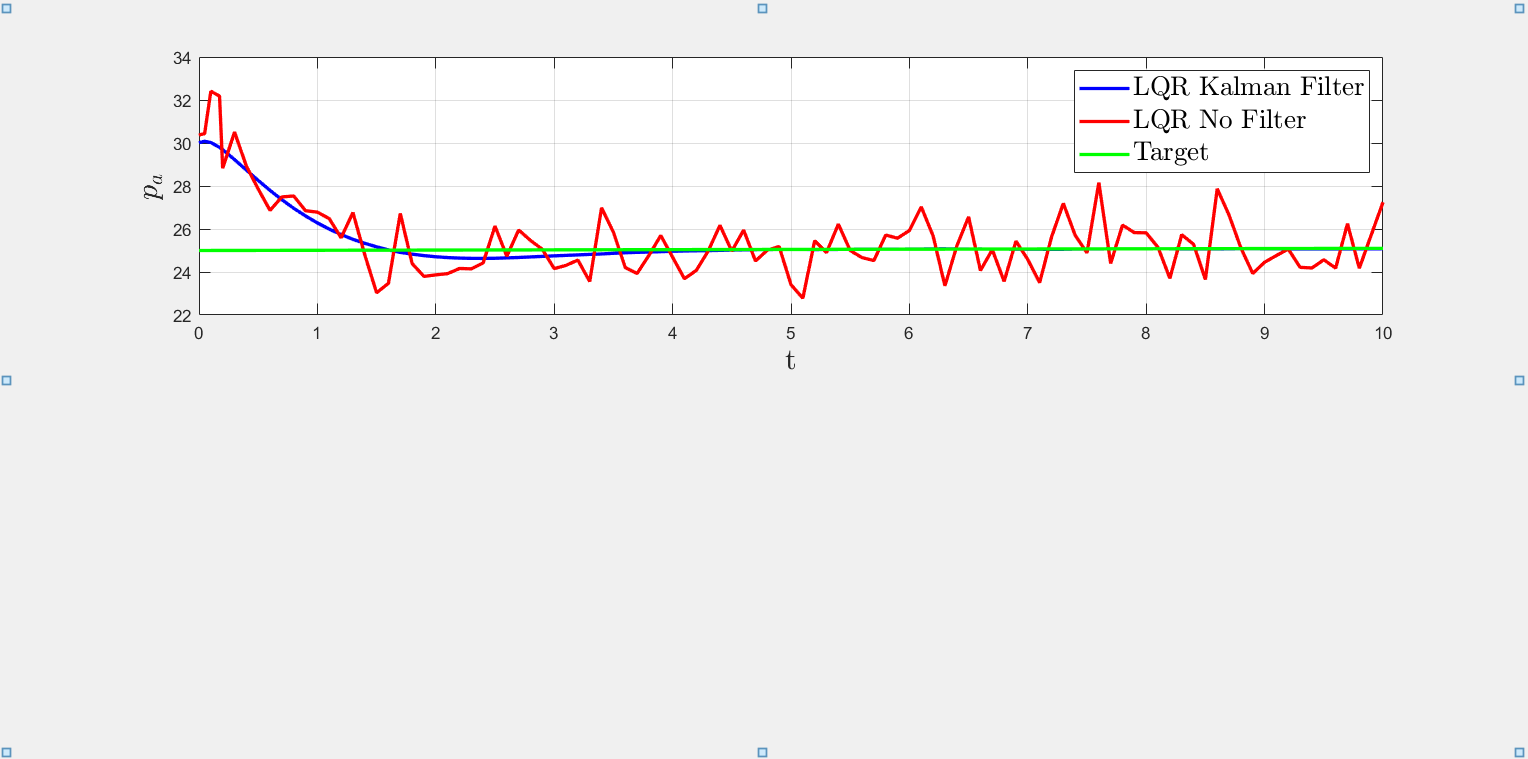

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off

Plot della risposta del sistema applicando PP con filtro di Kalman.

subplot(2, 1, 2);

control = 0;
out = sim('transcriptional_regulation_kalman_filter.slx');

pl = plot(out.t, out.p_a, 'Color', 'b');
set(pl,'linewidth',2);
leg = legend('PP Kalman Filter', 'Interpreter','Latex');
set(leg,'fontsize',16)
hold on
pl = plot(out.t, out.p_a_nofilter, 'Color', 'r', 'DisplayName','PP No Filter');
set(pl,'linewidth',2);
hold off
xlabel('t','Interpreter','Latex','FontSize',18)
ylabel('$p_a$','Interpreter','Latex','FontSize',18)
grid

Plot del riferimento.

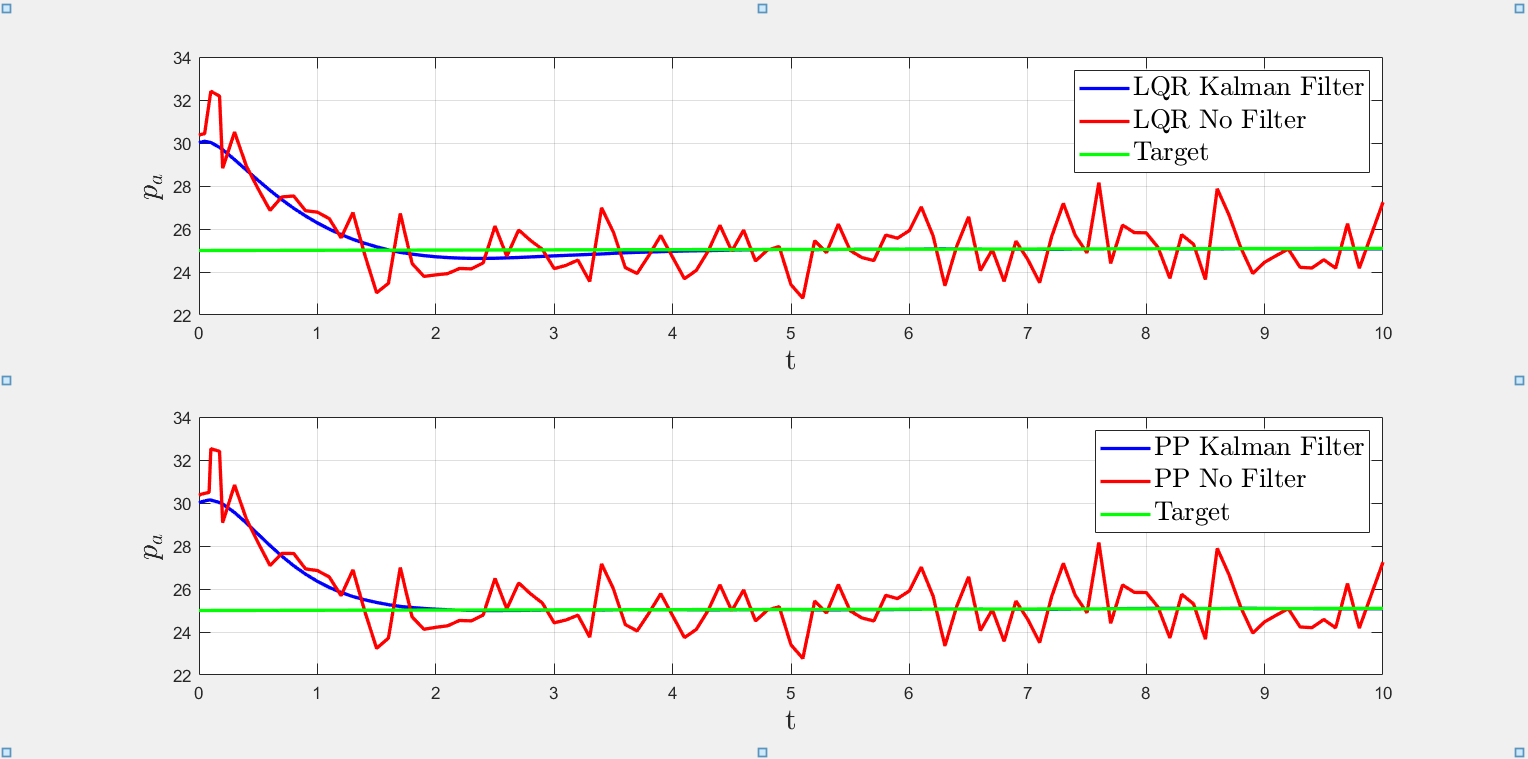

hold on
pl = plot(out.t, out.r, 'Color', 'g', 'DisplayName','Target');
set(pl,'linewidth',2);
hold off